load('amsr_n3125_Arctic_m03_y2025-v5.4.mat');

month = month_ts(1);
day = 12;
year = year_ts(1);

%% seaice concentration of the day to be studied 2D matrix
seaice = double(squeeze(seaice_ts(day,:,:)));

#### Parameters

%% Define the polynya region of interest (ROI),
latlim = [69.7, 70.8];
lonlim = [-24, -20.95];

% region to crop out
lat_crop_range = [];
lon_crop_range = [];

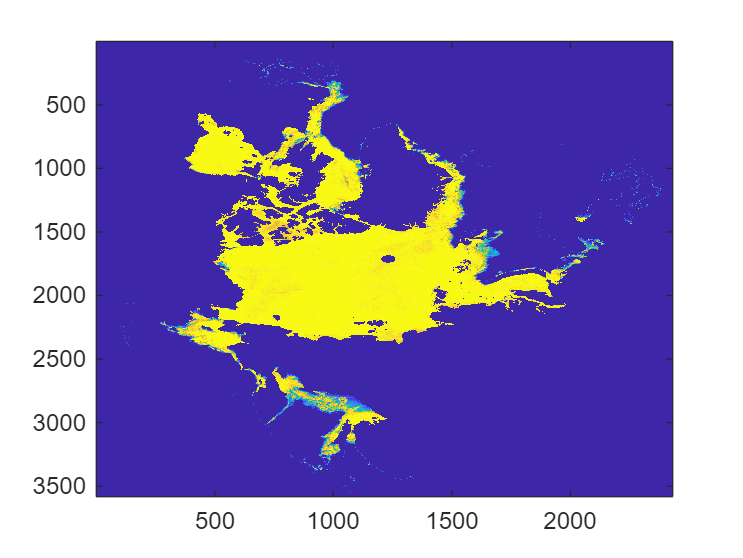

imagesc(seaice) 

%% x-axis 1350 to 1600
%% y-axis 900 - 1250

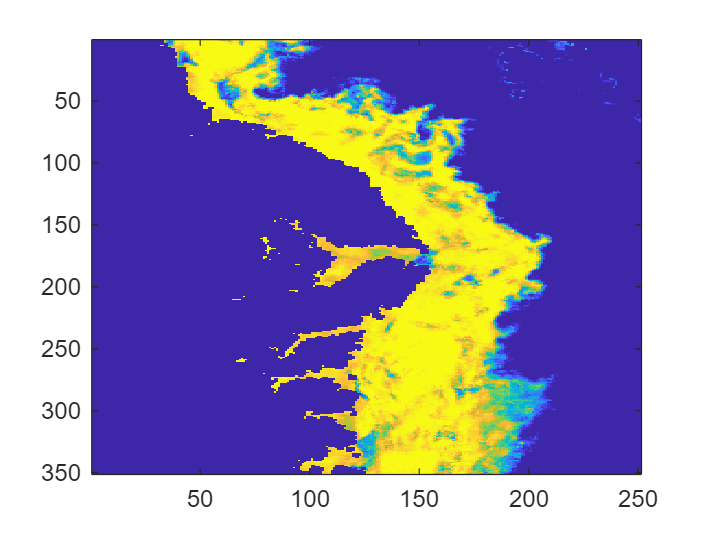

seacice_crop1 = seaice(900:1250, 1350:1600);
imagesc(seacice_crop1)

#### Lambert Projection of Sea Ice Concentration data

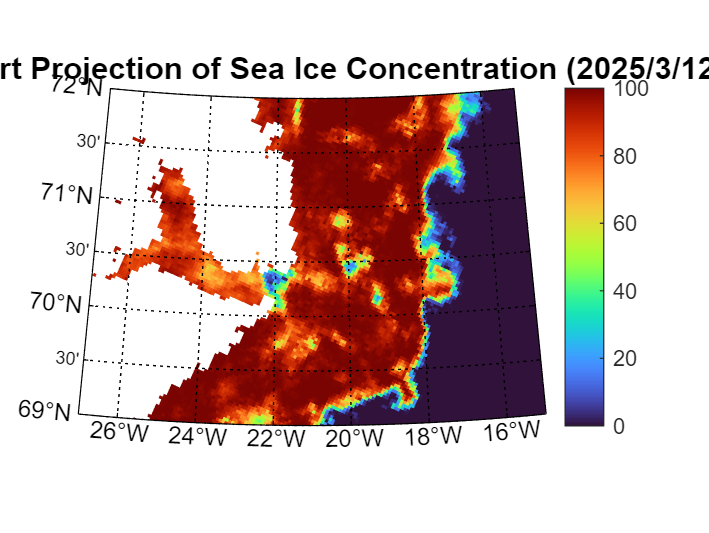

figure('Color','w');
hold on;

lat_crop1 = lat(900:1250, 1350:1600);
lon_crop1 = lon(900:1250, 1350:1600);

lat_show = [69 72];
lon_show = [-27 -15];

% Set up lambert projection
m_proj('lambert','long',lon_show,'lat',lat_show);

% Overlay sea ice concentration
m_pcolor(lon_crop1, lat_crop1, seacice_crop1);
shading flat;
colormap("turbo");
clim([0 100]);
colorbar;
title_string = sprintf('Lambert Projection of Sea Ice Concentration (%u/%u/%u)', year, month, day);
title(title_string, 'FontSize', 13);

% Add coastlines
% m_coast;    % The most basic coastline resolution is used
m_grid;

hold off;

% crop seaice_ts
seaice_ts_crop = seaice_ts(:, 900:1250, 1350:1600);
disp(size(seaice_ts_crop))

    31   351   251

